clc;
clear;
close all;

% Read the both matrix Excel files 
M1 = readmatrix('Matrix1.xlsx');
M2 = readmatrix('Matrix2.xlsx');

% First remove all the NaN;
valid_index = ~isnan(M2) & ~isnan(M1);
Matrix1 = M1(valid_index);
Matrix2 = M2(valid_index);

id = (1 : length(Matrix2))';
% create the new table 

moveis = table(id, Matrix1, Matrix2, 'VariableNames', {'Index', 'Matrix1', 'Matrix2'})

moveis = 830×3 table
    Index    Matrix1    Matrix2
    _____    _______    _______

      1          4        3.5  
      2        3.5        3.5  
      3        3.5          2  
      4        3.5        2.5  
      5          3          3  
      6        3.5        2.5  
      7        2.5        2.5  
      8          4        2.5  
      9          4          2  
     10        3.5          3  
     11          3          3  
     12        3.5        1.5  
     13        3.5        1.5  
     14        3.5        2.5  
     15          4        3.5  
     16          3          1  


summary(moveis)


moveis: 830×3 table

Variables:

    Index: double
    Matrix1: double
    Matrix2: double

Statistics for applicable variables:

               NumMissing     Min        Median         Max          Mean            Std     

    Index          0           1        415.5000        830        415.5000        239.7447  
    Matrix1        0           1          3.5000          4          3.3157          0.6336  
    Matrix2        0           0          2.5000          4          2.5211          0.8262  



% Add a new column with mean on the table
moveis.Average = mean([Matrix1, Matrix2], 2)

moveis = 830×4 table
    Index    Matrix1    Matrix2    Average
    _____    _______    _______    _______

      1          4        3.5       3.75  
      2        3.5        3.5        3.5  
      3        3.5          2       2.75  
      4        3.5        2.5          3  
      5          3          3          3  
      6        3.5        2.5          3  
      7        2.5        2.5        2.5  
      8          4        2.5       3.25  
      9          4          2          3  
     10        3.5          3       3.25  
     11          3          3          3  
     12        3.5        1.5        2.5  
     13        3.5        1.5        2.5  
     14        3.5        2.5          3  
     15          4        3.5       3.75  
     16          3          1          2  


%Now let us put the last row as the end with average info
moveis = [moveis; table(NaN, mean(Matrix1), mean(Matrix2), mean(moveis.Average), 'VariableNames', {'Index', 'Matrix1', 'Matrix2', 'Average'})]

moveis = 831×4 table
    Index    Matrix1    Matrix2    Average
    _____    _______    _______    _______

      1          4        3.5       3.75  
      2        3.5        3.5        3.5  
      3        3.5          2       2.75  
      4        3.5        2.5          3  
      5          3          3          3  
      6        3.5        2.5          3  
      7        2.5        2.5        2.5  
      8          4        2.5       3.25  
      9          4          2          3  
     10        3.5          3       3.25  
     11          3          3          3  
     12        3.5        1.5        2.5  
     13        3.5        1.5        2.5  
     14        3.5        2.5          3  
     15          4        3.5       3.75  
     16          3          1          2  


writetable(moveis,'movies.xlsx');

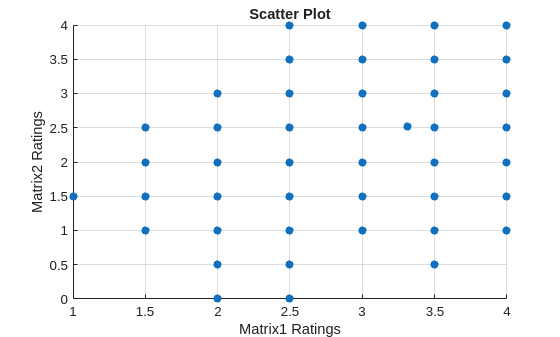


% Now plot the matrix 
figure;
h = scatter(moveis.Matrix1, moveis.Matrix2, 'filled');
xlabel('Matrix1 Ratings');
ylabel('Matrix2 Ratings');
title('Scatter Plot');
grid on;

saveas(h, 'movies.pdf');